# LAB2 - Problem 3

Goal: Design a linear-phase FIR high-pass filter to suppress DC/60 Hz noise. Requirement: attenuation at 60 Hz must be at least 40 dB. Output: create a NEW file named test_16k.wav (in current working folder).

clear; clc; close all;

## Setup

labDir = '/Users/hwy/Desktop/个人/26春/语音信号处理/lab2';
inputWav = fullfile(labDir, 'test_16k.wav');
outputWav = fullfile(pwd, 'test_16k_hp.wav');   % new file in current folder

if ~isfile(inputWav)
    error('Input file not found: %s', inputWav);
end

[x, fs] = audioread(inputWav);
if size(x,2) > 1
    x = mean(x, 2);
end
x = x(:);

## Step 1: Design linear-phase FIR high-pass filter

fStop = 60;      % stopband edge
fPass = 120;     % passband edge
targetAtt60 = 40;

[b, report] = designHighpassFIR(fs, fStop, fPass, targetAtt60);

fprintf('\nFilter design summary:\n');


Filter design summary:


fprintf('Length = %d taps\n', numel(b));

Length = 801 taps


fprintf('Cutoff (midpoint) = %.1f Hz\n', report.cutoffHz);

Cutoff (midpoint) = 90.0 Hz


fprintf('Attenuation at 60 Hz = %.2f dB\n', report.att60dB);

Attenuation at 60 Hz = 40.62 dB


fprintf('Gain at 120 Hz = %.2f dB\n', report.gain120dB);

Gain at 120 Hz = -0.08 dB


## Step 2: Filter speech and create new file

yFilt = conv(x, b, 'same');

% Additional quantitative checks requested:
% 1) DC offset mean before/after
% 2) 60 Hz band power ratio before/after
meanBefore = mean(x);
meanAfter = mean(yFilt);

bandHalfWidthHz = 1;  % evaluate 60 Hz +/- 1 Hz band
p60Before = bandPowerAroundFreq(x, fs, 60, bandHalfWidthHz);
p60After = bandPowerAroundFreq(yFilt, fs, 60, bandHalfWidthHz);
ratio60 = p60Before / (p60After + eps);
ratio60dB = 10 * log10(ratio60 + eps);

fprintf('\nAdditional checks:\n');


Additional checks:


fprintf('DC offset mean(x_before) = %.6e\n', meanBefore);

DC offset mean(x_before) = 2.281274e-04


fprintf('DC offset mean(x_after)  = %.6e\n', meanAfter);

DC offset mean(x_after)  = 3.672231e-07


fprintf('60 Hz band power before (%.0f+/-%.0f Hz) = %.6e\n', 60, bandHalfWidthHz, p60Before);

60 Hz band power before (60+/-1 Hz) = 9.544065e+01


fprintf('60 Hz band power after  (%.0f+/-%.0f Hz) = %.6e\n', 60, bandHalfWidthHz, p60After);

60 Hz band power after  (60+/-1 Hz) = 7.929861e-03


fprintf('60 Hz power ratio (before/after) = %.3f (%.2f dB reduction)\n', ratio60, ratio60dB);

60 Hz power ratio (before/after) = 12035.603 (40.80 dB reduction)



% Optional normalization for output file safety
y = yFilt;
peak = max(abs(y));
if peak > 0.999
    y = 0.999 * y / peak;
end

audiowrite(outputWav, y, fs);
fprintf('Saved filtered file: %s\n', outputWav);

Saved filtered file: /Users/hwy/Desktop/个人/26春/语音信号处理/lab2/test_16k_hp.wav


## Plot 1: FIR frequency response

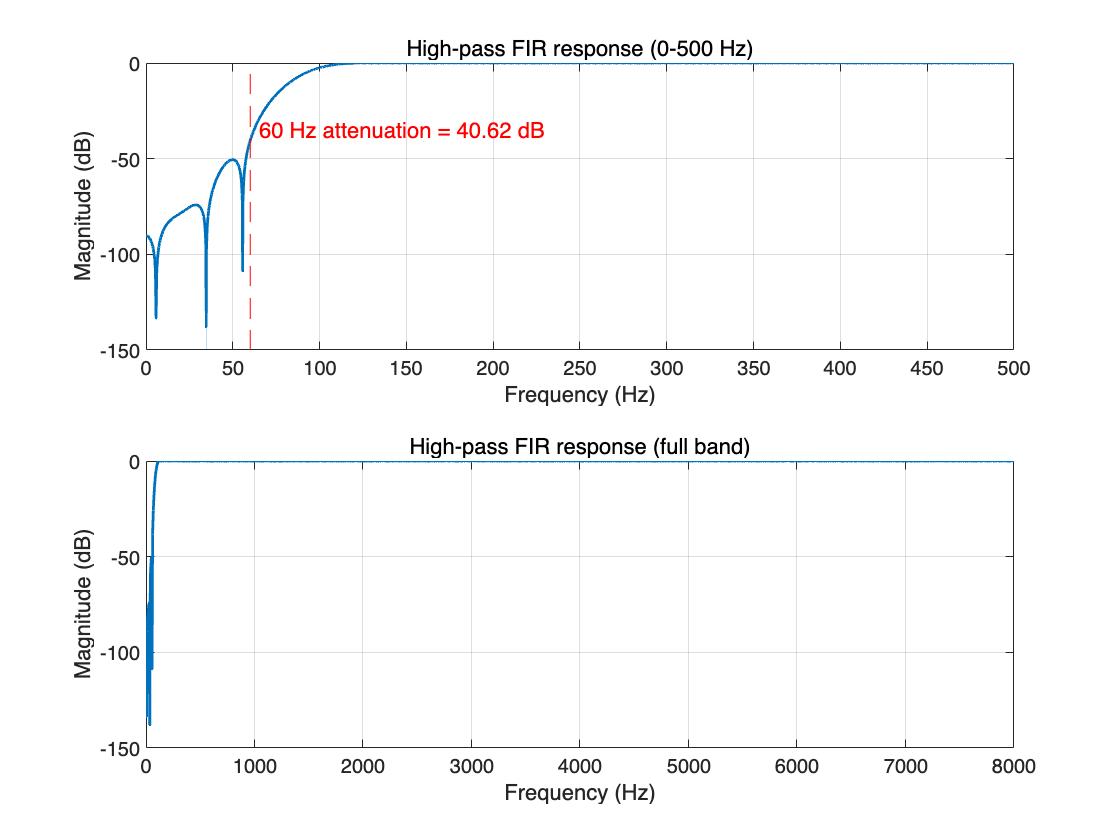

figure('Name', 'Problem 3 - FIR High-pass Response', 'Color', 'w');
subplot(2,1,1);
plot(report.freqHz, report.magDb, 'LineWidth', 1.4);
grid on; xlim([0 500]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('High-pass FIR response (0-500 Hz)');
line([60 60], ylim, 'Color', 'r', 'LineStyle', '--');
text(65, -35, sprintf('60 Hz attenuation = %.2f dB', report.att60dB), 'Color', 'r');

subplot(2,1,2);
plot(report.freqHz, report.magDb, 'LineWidth', 1.4);
grid on; xlim([0 fs/2]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('High-pass FIR response (full band)');

## Plot 2: Before/after spectra and short waveform

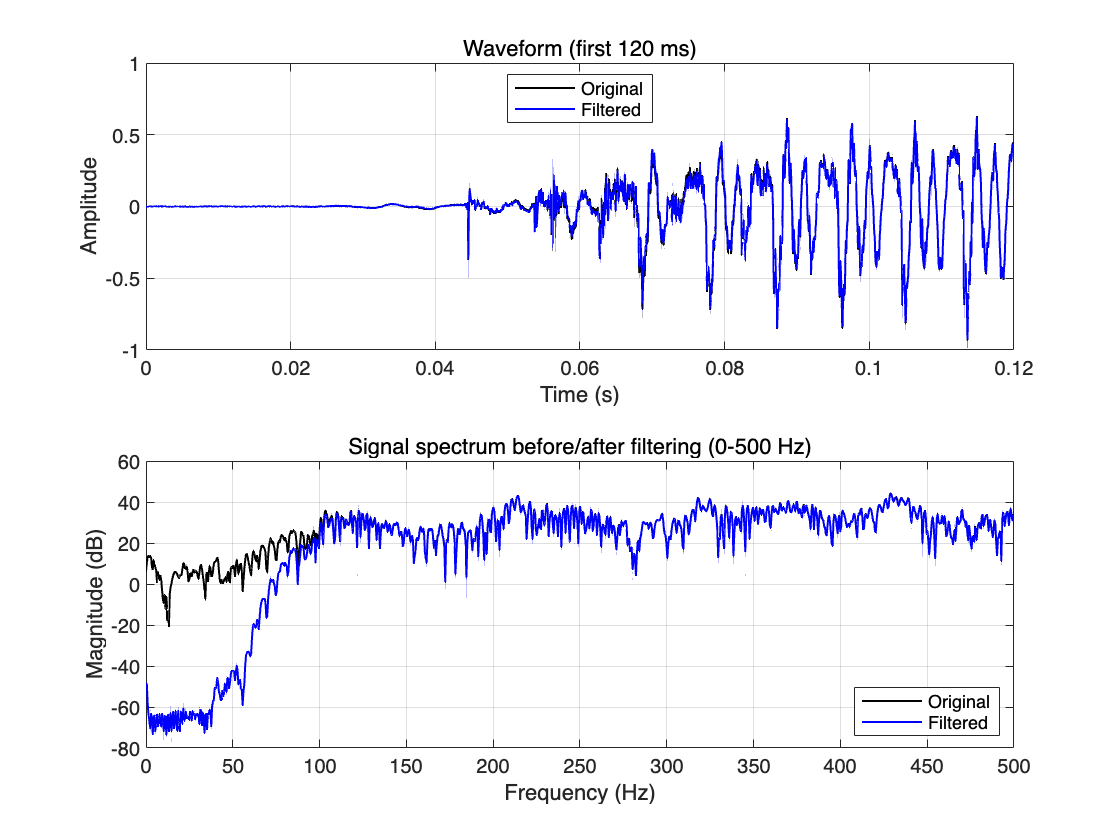

[fSig, inDb] = oneSidedSpectrum(x, fs);
[~, outDb] = oneSidedSpectrum(y, fs);

t = (0:numel(x)-1).' / fs;
showN = min(numel(t), round(0.12 * fs));

figure('Name', 'Problem 3 - Before vs After', 'Color', 'w');
subplot(2,1,1);
plot(t(1:showN), x(1:showN), 'k', 'LineWidth', 1.0); hold on;
plot(t(1:showN), y(1:showN), 'b', 'LineWidth', 1.0);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform (first 120 ms)');
legend('Original', 'Filtered', 'Location', 'best');

subplot(2,1,2);
plot(fSig, inDb, 'k', 'LineWidth', 1.0); hold on;
plot(fSig, outDb, 'b', 'LineWidth', 1.0);
grid on; xlim([0 500]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Signal spectrum before/after filtering (0-500 Hz)');
legend('Original', 'Filtered', 'Location', 'best');


fprintf('\nDone. Please listen to output file and verify DC/60 Hz hum is reduced.\n');


Done. Please listen to output file and verify DC/60 Hz hum is reduced.


## Local functions

function [b, report] = designHighpassFIR(fs, fStop, fPass, targetAtt60)
    cutoffHz = (fStop + fPass) / 2;
    found = false;

    for L = 201:100:5001
        bTmp = windowedSincHighpass(L, cutoffHz, fs);
        [f, mag] = firMagResponse(bTmp, fs, 262144);

        % Normalize passband gain near 2 kHz to 0 dB.
        passRef = interp1(f, mag, 2000, 'linear', 'extrap');
        mag = mag / (passRef + eps);

        att60 = -20*log10(interp1(f, mag, 60, 'linear', 'extrap') + eps);
        gain120 = 20*log10(interp1(f, mag, 120, 'linear', 'extrap') + eps);

        if att60 >= targetAtt60
            found = true;
            b = bTmp;
            break;
        end
    end

    if ~found
        error('Could not meet %.1f dB attenuation at 60 Hz in the search range.', targetAtt60);
    end

    report.cutoffHz = cutoffHz;
    report.att60dB = att60;
    report.gain120dB = gain120;
    report.freqHz = f;
    report.magDb = 20*log10(mag + eps);
end

function b = windowedSincHighpass(L, fc, fs)
    n = (0:L-1).' - (L-1)/2;
    hLow = (2*fc/fs) * sinc(2*fc*n/fs);

    % Spectral inversion: high-pass from low-pass
    hHigh = -hLow;
    hHigh((L+1)/2) = hHigh((L+1)/2) + 1;

    w = hammingManual(L);
    b = hHigh .* w;
end

function w = hammingManual(L)
    n = (0:L-1).';
    if L == 1
        w = 1;
    else
        w = 0.54 - 0.46*cos(2*pi*n/(L-1));
    end
end

function [f, mag] = firMagResponse(b, fs, nfft)
    H = fft(b, nfft);
    H = H(1:nfft/2+1);
    mag = abs(H);
    f = (0:nfft/2).' * fs / nfft;
end

function [f, magDb] = oneSidedSpectrum(x, fs)
    x = x(:) - mean(x);
    N = numel(x);
    nfft = 2^nextpow2(max(N, 1024));
    w = hammingManual(N);
    X = fft(x .* w, nfft);
    X = X(1:nfft/2+1);
    f = (0:nfft/2).' * fs / nfft;
    magDb = 20*log10(abs(X) + 1e-12);
end

function p = bandPowerAroundFreq(x, fs, f0, bandHalfWidthHz)
    x = x(:) - mean(x);
    N = numel(x);
    nfft = 2^nextpow2(max(N, 8*fs));
    w = hammingManual(N);
    X = fft(x .* w, nfft);
    X = X(1:nfft/2+1);
    f = (0:nfft/2).' * fs / nfft;
    P = abs(X).^2;

    idx = abs(f - f0) <= bandHalfWidthHz;
    if ~any(idx)
        [~, k] = min(abs(f - f0));
        idx(k) = true;
    end

    p = sum(P(idx));
end